 clear all
 close all


## Construction du système discret

%dimensions du domaine
%ordre 2 décentré
lx = 1;
ly = 1;

%nombre de points dans chaque dimension
Nx = 50;
Ny = 50;
% pas de discretisation
h = lx/(Nx+1);
k = ly/(1+Ny);

a = k^2/(2*(h^2 + k^2));
b = h^2/(2*(h^2 + k^2));
c = (k^2)*(h^2)/(2*(h^2 + k^2));

% construction du système linéaire
temp = a*ones(Nx-1,1);
A = eye(Nx) - diag(temp,1) - diag(temp,-1);
B = b*eye(Nx);

M = zeros(Nx*Ny);
M(1:Nx,1:Nx) = 3*eye(Nx);
M(1:Nx,Nx+1:2*Nx)=-4*eye(Nx);
M(1:Nx,2*Nx+1:3*Nx) = eye(Nx);
for i=2:Ny
    M((i-1)*Nx+1:i*Nx,(i-1)*Nx+1:i*Nx) = A;
    M((i-1)*Nx+1:i*Nx,(i-2)*Nx+1:(i-1)*Nx) = -B;
    if i < Ny
        M((i-1)*Nx+1:i*Nx,i*Nx+1:(i+1)*Nx) = -B;
    end
end
%construction second membre
N = zeros(Nx*Ny,1);
x=linspace(h,lx,Nx);
y=linspace(k,ly,Ny);

for i=1:Nx
    N(i) = 2*k*g(x(i),lx,ly);
end
N

N =    -0.0076
   -0.0153
   -0.0229
   -0.0305
   -0.0379
   -0.0452
   -0.0523
   -0.0592
   -0.0659
   -0.0723


 
for j=1:Ny
    for i=1:Nx
        p = i + (j-1)*Nx;
        N(p)= N(p) - c*f(x(i),y(j),lx,ly);
    end 
end 

%résolution

U = M\N;
% affichage de la solution 
u=zeros(Nx+2,Ny+2);
Uth = u;
for j=1:Ny
    for i = 1:Nx
        p= i +(j-1)*Nx;
        u(i+1,j+1)=U(p,1);
        Uth(i+1,j+1) = uth(x(i),y(j),lx,ly);
    end
end
u

u =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0037    0.0075    0.0112    0.0150    0.0187    0.0223    0.0258    0.0293    0.0326    0.0358    0.0388    0.0417    0.0444    0.0470    0.0493    0.0515    0.0535    0.0553    0.0568    0.0581    0.0593    0.0601    0.0608    0.0612    0.0613    0.0613    0.0610    0.0604    0.0597    0.0587    0.0574    0.0560    0.0544    0.0525    0.0504    0.0482    0.0458    0.0432    0.0404    0.0376    0.0345    0.0314    0.0281    0.0248    0.0214    0.0179    0.0143    0.0108    0

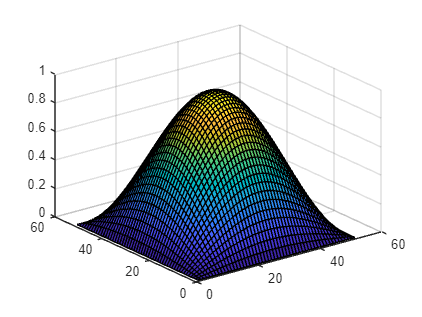

%[X,Y] = meshgrid(0:h:lx,0:k:ly)
%erreur
eps = abs(u-Uth);
surf(u)

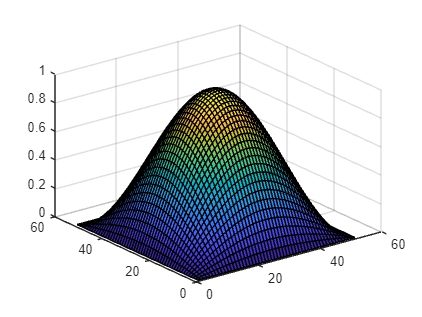

surf(Uth)

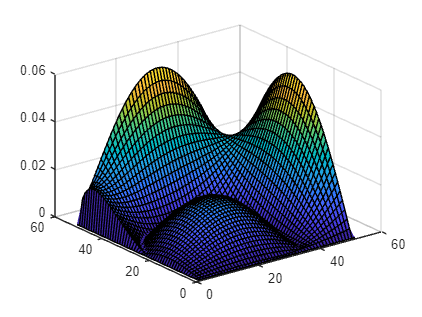

surf(eps)

N

N =    -0.0076
   -0.0153
   -0.0229
   -0.0305
   -0.0379
   -0.0452
   -0.0523
   -0.0592
   -0.0658
   -0.0722
